clear; clc;
close all;
addpath('../functions', '../data')

The D'Agostino-Pearson's K2 test indicates that the transformed precipitation is NORMAL distributed.


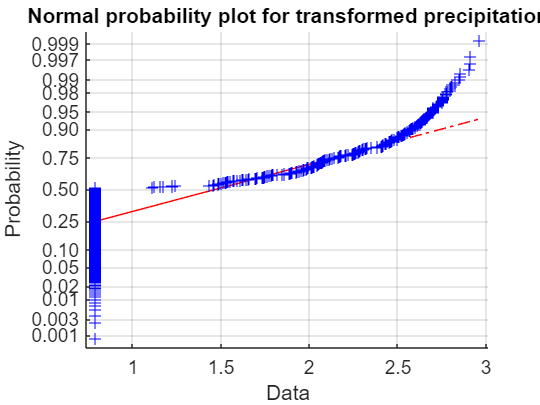

ans = logical
   1


% Load data
load proj23.mat
load rain_rec.mat
load transformed2.mat

t_int = ElGeneina.rain_t;
t_org= ElGeneina.rain_org_t;
ndvi = ElGeneina.nvdi;

% Rescale the vegitation data so it is between -1 and 1
rendvi = (ndvi/255)*2 -1;
t_ndvi = ElGeneina.nvdi_t;

% Syncing the input and output
t = t_int(793:end);
x = transformed_rain2(793:end)'; % use for model 1 and 2

% Transform data to make it more normally distributed
x = log(x+6); % 
y = log(rendvi); % 
%checkIfNormal(log(rendvi),'rescaled ndvi')
checkIfNormal(x,'transformed precipitation')

% Data split
%-------------
% Training
trainx = x(1:450);
validx = x(451:551);
testx = x(552:end);
% Validation 
trainn = y(1:450);
validn = y(451:551);
testn = y(552:end);
% Testing
train_t = t(1:450);
valid_t = t(451:551);
test_t = t(552:end);

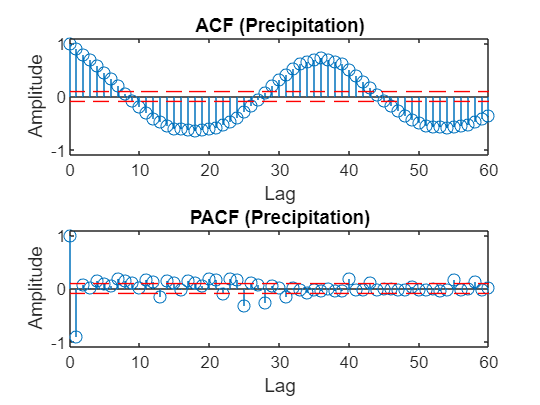

% Make a model for the input to help us do: 
% 1) prediction of input 
% 2) find model orders for the BJ (d,r,s)
x = trainx-mean(trainx);
plotACFnPACF(x,60,'Precipitation');

% Model 
Ax = [1 0 0 1 0 0 0 0 0 0 0 0 1 0 0 0 zeros(1,20) -1];
Cx = [1 1 1 zeros(1,9) 0.5];

poly = idpoly(Ax,[],Cx);
poly.Structure.a.Free = Ax;
poly.Structure.c.Free = Cx;
model = pem(x,poly);
residual = filter(model.a,model.c,x);

% Saving the model
A3 = model.a;
C3 = model.c; 

% Residual analysis:
%----------------------
present(model)

                                                                                               
model =                                                                                        
Discrete-time ARMA model: A(z)y(t) = C(z)e(t)                                                  
  A(z) = 1 - 0.417 (+/- 0.04052) z^-3 + 0.2063 (+/- 0.02995) z^-12 - 0.4637 (+/- 0.04012) z^-36
                                                                                               
  C(z) = 1 + 1.021 (+/- 0.02423) z^-1 + 0.9553 (+/- 0.02764) z^-2 + 0.0419 (+/- 0.02432) z^-12 
                                                                                               
Sample time: 1 seconds                                                                         
                                                                                               
Parameterization:                                                                              
   Polynomial orders:   na=36   nc=12   


plotACFnPACF(residual(length(A3):end),37,'Precipitation model residual');

checkIfWhite(residual(length(A3):end))

The residual is deemed to be WHITE according to the Monti-test (as 20.26 < 31.41).


ans = logical
   1


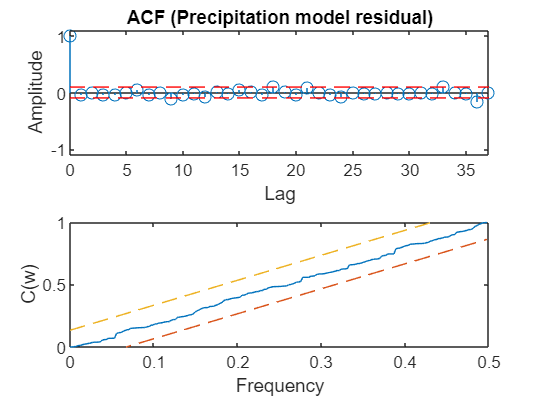

Whiteness test with 5% significance
  Ljung-Box-Pierce test: 1 (white if 24.63 < 36.42)
  McLeod-Li test:        0 (white if 120.98 < 36.42)
  Monti test:            1 (white if 25.54 < 36.42)
  Sign change test:      0 (white if 0.65 in [0.45,0.55])


whitenessTest(residual(length(A3):end))

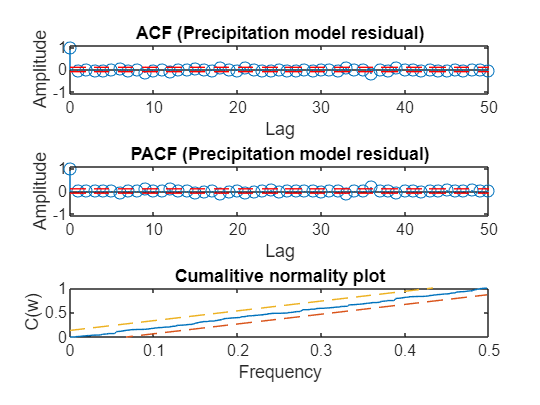


data = residual(length(A3):end);
figure
subplot(311)
acfEst = acf( data, 50, 0.05, 1 );
title( sprintf('ACF (%s)','Precipitation model residual'))
subplot(312)
pacfEst = pacf( data, 50, 0.05, 1 );
title( sprintf('PACF (%s)','Precipitation model residual'))
subplot(313)
plotCumPer( data, 0.05, 1 );
title('Cumalitive normality plot')

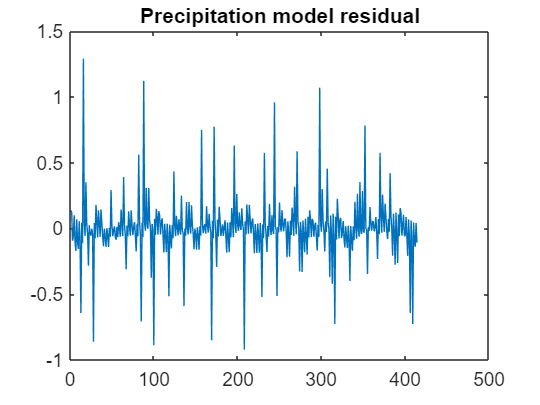

% An estimate for the variance of the noise (need this for linear predictor)
var_ex = var(residual(length(A3):end));
figure
plot(data)
title('Precipitation model residual')

% Estimating the (d,r,s) model orders for the Box jenkins model 
% y_t = (Bz^(-d)/A2) x_t + C/A1 e_t
x = trainx-mean(trainx);
y = trainn-mean(trainn);
t = train_t;


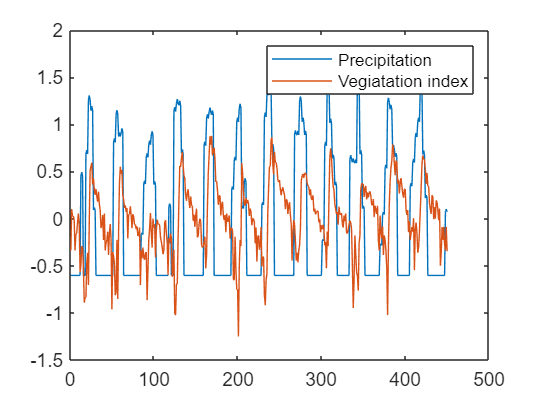

% Plotting the input and output to see if there is any correlations we
% might be able to use
figure
plot(x);
hold on 
plot( y)
hold off
legend('Precipitation','Vegiatation index')

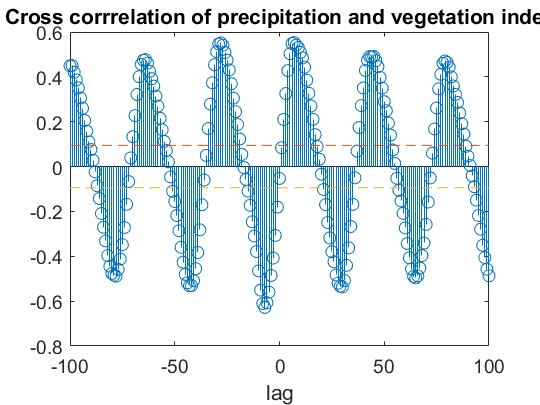


% Cross correlation between vegetation and rain
figure
n = length(y);
M = 100; 
stem(-M:M, crosscorr(x, y, M)); 
title('Cross corrrelation of precipitation and vegetation index'), xlabel('lag')
hold on
plot(-M:M, 2/sqrt(n)*ones(1, 2*M+1), '--')
plot(-M:M, -2/sqrt(n)*ones(1, 2*M+1), '--')
hold off

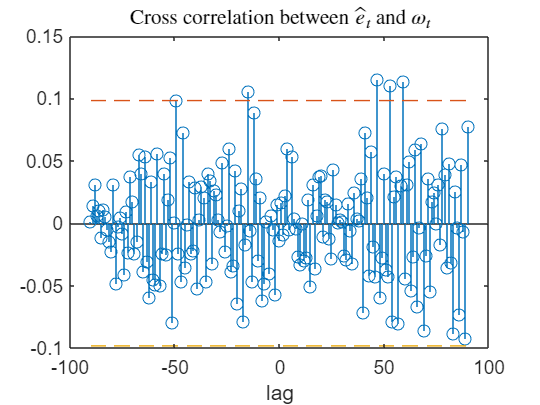

% Prewhitening of y
eps_t = filter(A3, C3, y); eps_t = eps_t(length(A3):end);
w_t = filter(A3, C3, x); w_t = w_t(length(A3):end);
% Cross correlation 
figure
n = length(eps_t);
M = 90; 
stem(-M:M, crosscorr(w_t, eps_t, M)); 
titletext = 'Cross correlation between $\hat{e}_t$ and $\omega_t$';
title(titletext,'Interpreter', 'latex')
xlabel('lag')
hold on
plot(-M:M, 2/sqrt(n)*ones(1, 2*M+1), '--')
plot(-M:M, -2/sqrt(n)*ones(1, 2*M+1), '--')
hold off

%now we need to estimate the d r s parameters 
%estimate B and A2


B= [0 0 1 1 1 1]; %ok2
A2 = [1 1 1];

B = [0 0 0 1 1 1 1 0 0 1]; % Gives no correlation at all but there is problem with stability
A2= [1 1 1];

B = [0 0 0 0 1] % ok1 use this one

B =      0     0     0     0     1


A2 = [1 1]

A2 =      1     1



Mi = idpoly([1], B, [], [], A2); 
Mi.Structure.B.Free = B;
Mi.Structure.F.Free = A2;
z = iddata(y, x);
Mba2 = pem(z, Mi);

present(Mba2) 

                                                                              
Mba2 =                                                                        
Discrete-time OE model: y(t) = [B(z)/F(z)]u(t) + e(t)                         
  B(z) = 0.06978 (+/- 0.007787) z^-4                                          
                                                                              
  F(z) = 1 - 0.908 (+/- 0.0204) z^-1                                          
                                                                              
Sample time: 1 seconds                                                        
                                                                              
Parameterization:                                                             
   Polynomial orders:   nb=1   nf=1   nk=4                                    
   Number of free coefficients: 2                                             
   Use "polydata", "getpvec", "getcov" for parameter

xf = filter(Mba2.b,Mba2.f, x);   
etilde = y - xf; 

% Saving the found model
B=Mba2.b ;
A2 = Mba2.f;



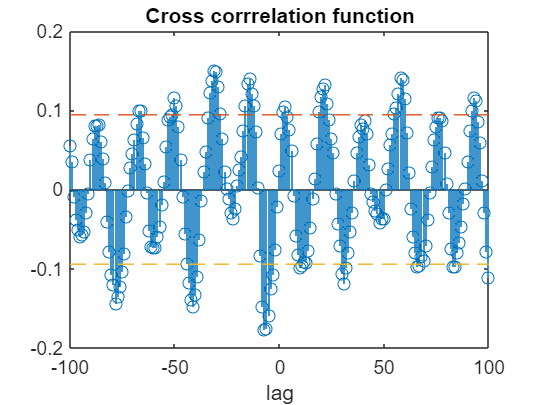


figure
n = length(etilde);
M = 100; stem(-M:M, crosscorr(x, etilde, M)); 
title('Cross corrrelation function'), xlabel('lag')
hold on
plot(-M:M, 2/sqrt(n)*ones(1, 2*M+1), '--')
plot(-M:M, -2/sqrt(n)*ones(1, 2*M+1), '--')
hold off

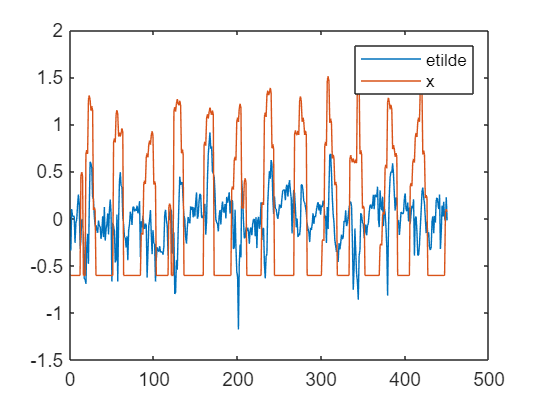

plot(etilde)
hold on
plot(x)
hold off
legend('etilde','x')

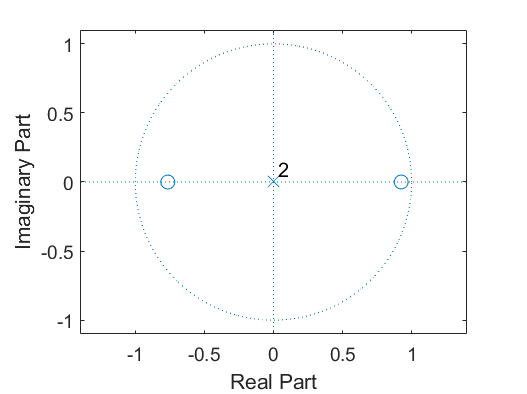

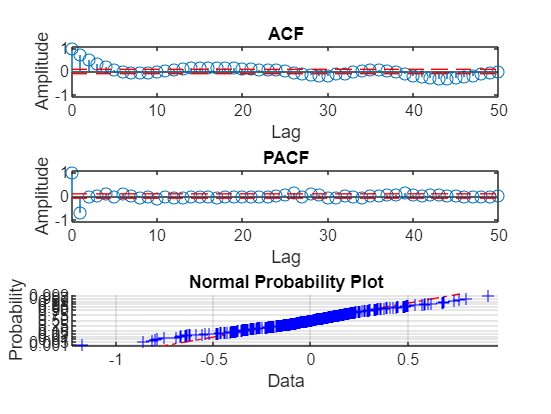

% if predictions are too noisy check stability of polynomials
%figure; 
%zplane(A2)

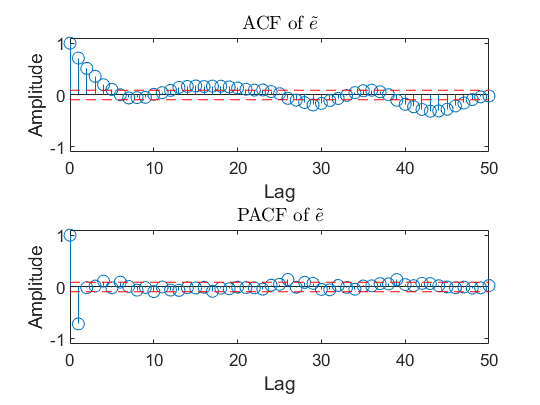

e_hat = etilde;

data = e_hat;
subplot(211)
acfEst = acf( data, 50, 0.05, 1 );
title( sprintf('ACF of %s','$\tilde{e}$'),'Interpreter','latex')
subplot(212)
pacfEst = pacf( data, 50, 0.05, 1 );
title( sprintf('PACF of %s','$\tilde{e}$'),'Interpreter','latex')

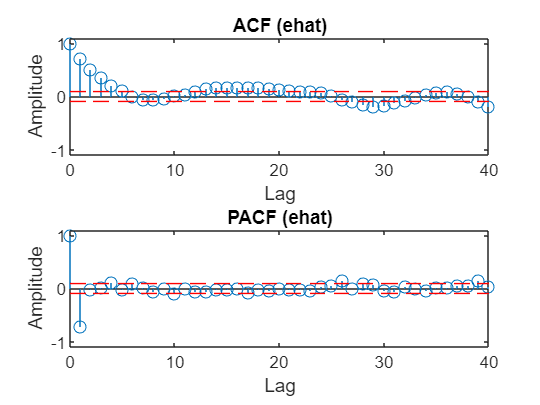

plotACFnPACF(e_hat,40,'ehat');

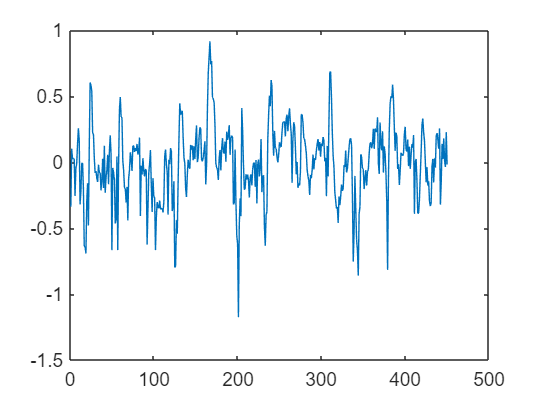

figure
plot(e_hat)

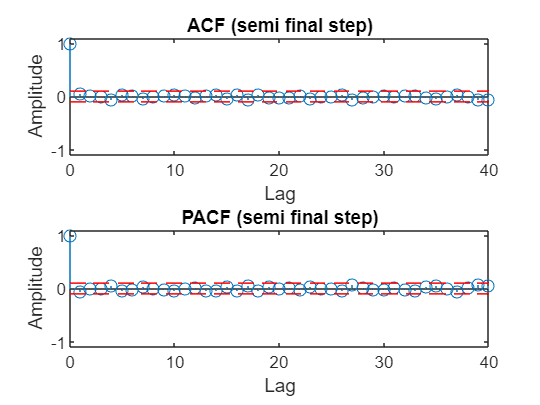

% Now estimating A1 and C1

A1 = [1 1 zeros(1,34) 0]; 
C1 = [1 zeros(1,35) 0.5];


polye_hat = idpoly(A1,[],C1);
%polye_hat.Structure.c.Free = C1;
polye_hat.Structure.a.Free = A1;
Ma1c1 = pem(e_hat,polye_hat);
e = filter(Ma1c1.a,Ma1c1.c,e_hat);
e = e(length(A1)+1:end);

% Residual analysis:
plotACFnPACF(e(length(A1):end),40,'semi final step');

present(Ma1c1)

                                                                                                                                    
Ma1c1 =                                                                                                                             
Discrete-time ARMA model: A(z)y(t) = C(z)e(t)                                                                                       
  A(z) = 1 - 0.5662 (+/- 0.6353) z^-1                                                                                               
                                                                                                                                    
                                                                                                                                    
  C(z) = 1 + 0.09862 (+/- 0.6335) z^-1 + 0.09297 (+/- 0.423) z^-2 + 0.1449 (+/- 0.3009) z^-3 + 0.001017 (+/- 0.2661) z^-4           
          + 0.04604 (+/- 0.1619) z^-5 - 0.006395 (+/- 0.1266) z^-6 - 

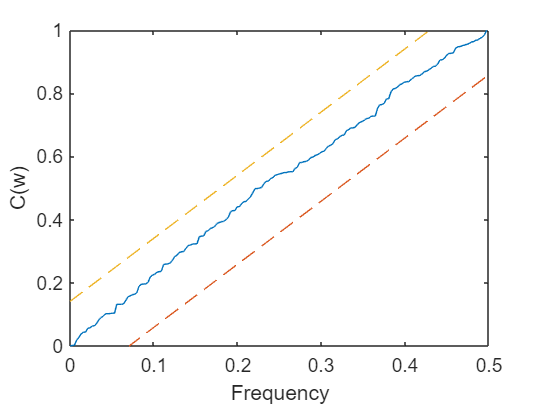

Whiteness test with 5% significance
  Ljung-Box-Pierce test: 1 (white if  9.07 < 36.42)
  McLeod-Li test:        0 (white if 70.91 < 36.42)
  Monti test:            1 (white if 10.39 < 36.42)
  Sign change test:      1 (white if 0.50 in [0.45,0.55])


figure
whitenessTest(e(length(A1):end))

% 

Mi = idpoly(1 ,B, C1, A1 , A2 ) ;
Mi.Structure.F.Free = A2;
Mi.Structure.B.Free = B;
Mi.Structure.D.Free = A1;
Mi.Structure.C.Free = C1;
z = iddata(y,x);
MboxJ = pem(z,Mi) ;
ehat = resid( MboxJ , z );

% Residual analysis
present( MboxJ );

                                                                              
MboxJ =                                                                       
Discrete-time BJ model: y(t) = [B(z)/F(z)]u(t) + [C(z)/D(z)]e(t)              
  B(z) = 0.06916 (+/- 0.01005) z^-4                                           
                                                                              
  C(z) = 1 + 0.07622 (+/- 0.04854) z^-36                                      
                                                                              
  D(z) = 1 - 0.7146 (+/- 0.03496) z^-1                                        
                                                                              
  F(z) = 1 - 0.8963 (+/- 0.0281) z^-1                                         
                                                                              
Sample time: 1 seconds                                                        
                                                    

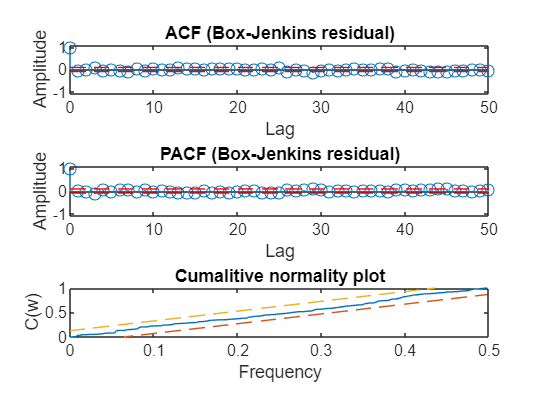

data = ehat.y;
subplot(311)
acfEst = acf( data, 50, 0.05, 1 );
title( sprintf('ACF (%s)','Box-Jenkins residual'))
subplot(312)
pacfEst = pacf( data, 50, 0.05, 1 );
title( sprintf('PACF (%s)','Box-Jenkins residual'))
subplot(313)
plotCumPer( data, 0.05, 1 );
title('Cumalitive normality plot')

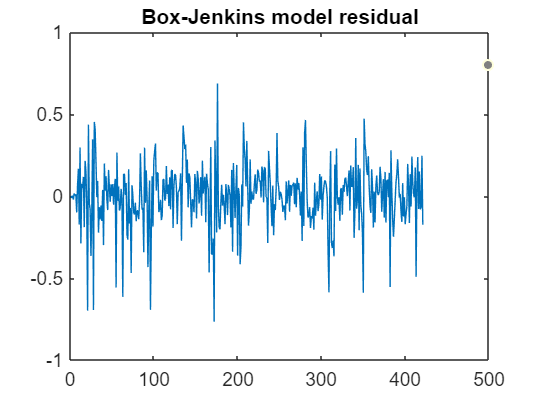

figure
plot(ehat.y(30:end))
title('Box-Jenkins model residual')


% Estimating the noise variance (used in the linear predictions)
var_ey = var(ehat.y(100:end));

% Saving the found model: (save the MboxJ object and A3,C3 so you can use it in Task C)
A1 = MboxJ.d;
A2 = MboxJ.f;
B  = MboxJ.b;
C1 = MboxJ.c;
% Save MboxJ in the project folder we going to use it for Task C
length(A1) 

ans = 37

length(A2)

ans = 2

length(B)

ans = 5

length(C1)

ans = 37

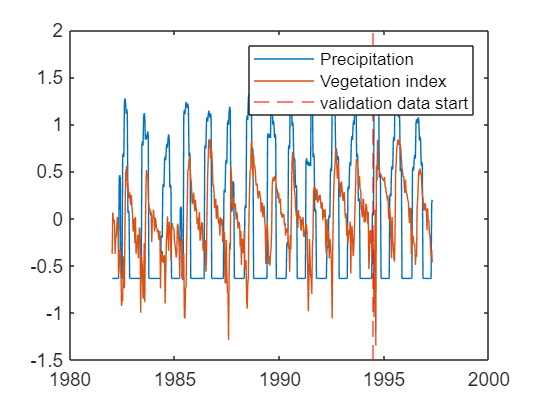

%now let's validate the model

y = [trainn;validn];
my = mean(y);
y = y-my; % Save the mean so we can add it back at the end
x = [trainx;validx]; x= x-mean(x);
validstart = train_t(end);
t = [train_t;valid_t];

figure;
plot(t,x);
hold on
plot(t,y);
xline(validstart, '--', 'Color', 'red');
hold off
legend('Precipitation','Vegetation index','validation data start')

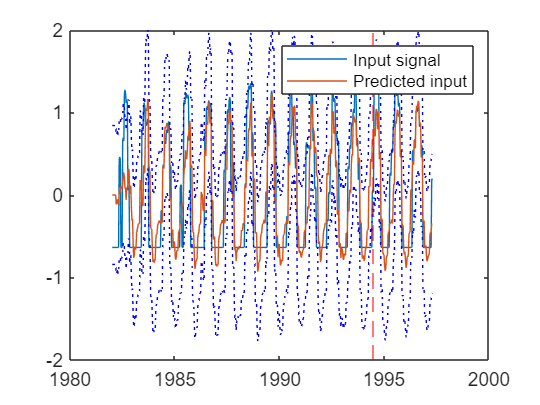

% Lets predict the input first
% ------------------------------
k = 7; % k step predictions
[Fx, Gx] = polydiv( C3, A3, k );
xhat = filter(Gx, C3, x);
var_xk = sum(Fx.^2)*var_ex;
    
figure
plot(t,x)
hold on
plot(t,xhat)
plot(t,  xhat + 2*sqrt(var_xk),':', 'Color', 'blue' )
plot( t, xhat - 2*sqrt(var_xk),':', 'Color', 'blue' )
xline(validstart, '--', 'Color', 'red');

hold off
ylim([-2, 2]);
legend('Input signal', 'Predicted input')

CI = 1.96*sqrt(var_xk);
erk = xhat - x;
EP = sum(abs(erk) > CI) / length(erk)

EP = 0.0635

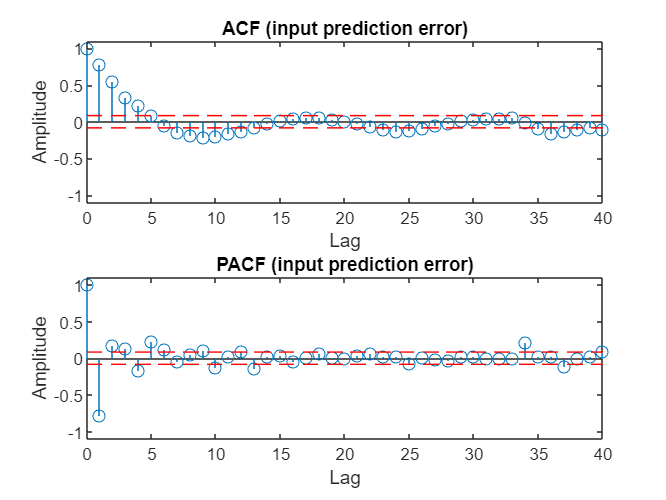

pred_ex = x-xhat;
plotACFnPACF(pred_ex,40,'input prediction error');

The D'Agostino-Pearson's K2 test indicates that the input is NORMAL distributed.


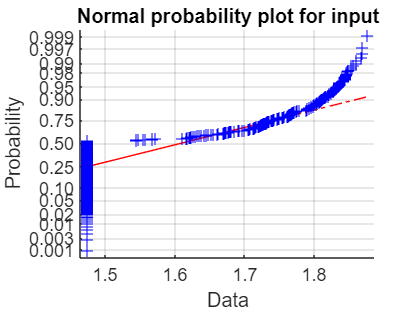

ans = logical
   1


checkIfNormal(log(x+5),'input')

% Now predict the vegetation
A = conv( A1, A2 );
B2 = conv( A1, B ); 
C = conv( A2, C1 );
k3 = k;
 

[Fk,Gk] = polydiv(C, A, k ) ;
 

[ F_hatk,G_hatk] = polydiv(conv(Fk,B2),C,k);
 


a = filter(F_hatk,[1],xhat);
b = filter(G_hatk,C,x);
c = filter(Gk,C,y);
y_hatk =a+ b + c;
error_k = y_hatk-y;
var_yk = sum(Fk.^2)*var_ey + sum(F_hatk.^2)*var_xk;

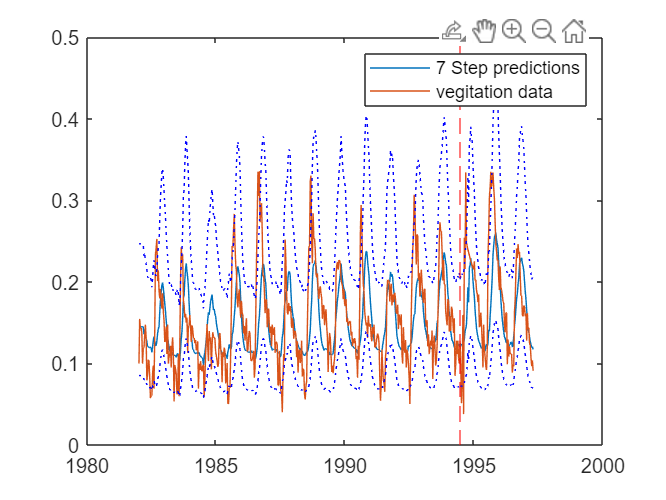

% Transform back when showing results
figure;
plot(t,exp(y_hatk+my))

hold on
plot(t,exp(my+y))
plot(t,  exp(my+y_hatk + 2*sqrt(var_yk)),':', 'Color', 'blue' )
plot(t,  exp(my+y_hatk - 2*sqrt(var_yk)),':', 'Color', 'blue' )
xline(validstart, '--', 'Color', 'red');
hold off

legend(sprintf('%d Step predictions',k),'vegitation data')

% Checking the confidence intervals
CI = 1.96*sqrt(var_yk);
erk = y_hatk - y;
EP = sum(abs(erk) > CI) / length(erk)

EP = 0.0799

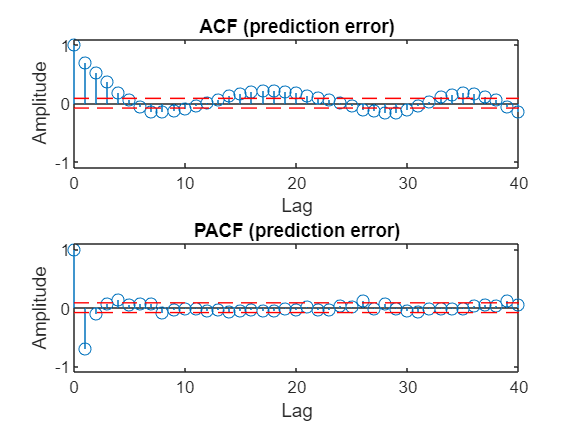

% Analysing the prediction error
pred_e = y-y_hatk;
plotACFnPACF(pred_e,40,'prediction error');

% variance of the prediction error
var(pred_e)

ans = 0.0916

% mse of prediction error